# **Huffman BMOCZ with Zero Rotation**

**Description:** In this example, we transmit a Huffman polynomial through an AWGN channel and decode under a random phase rotation of the received zeros. 

The example illustrates Huffman BMOCZ, the oversampled (IDFT-based) direct zero-testing (DiZeT) decoder, and an affine cyclically permutable code (ACPC). The following functions are used:

- 
$$\texttt{loadACPCarrays()}$$


- 
$$\texttt{acpcEncode()}$$


- 
$$\texttt{jbmoczMessageToPoly()}$$


- 
$$\texttt{idftDizet()}$$


- 
$$\texttt{acpcDecode()}$$


**Before starting:** ensure that your working directory is the "\examples" folder.

Add the "\functions" folder to your MATLAB path and get the full path of the folder containing the ACPC arrays.

clear; close all; clc;

% Get current path and parent directory
currentFolder = pwd;
parentFolder = fileparts(currentFolder);

% Add functions to current path
addpath(strcat(parentFolder, '\functions'))

% Get path to ACPC arrays 
acpcArraysFolder = strcat(parentFolder, '\acpcArrays');

Set the Huffman BMOCZ zero constellation parameters.

**Note:** You must choose either $\texttt{K} = 31$or $\texttt{K} = 127$, as these are the only supported codewords lengths for the ACPC implementation.

K = 31;                     % Number of zeros 
R = sqrt(1 + sin(pi/K));    % Radius

% Define the number of bits encoded per polynomial
if K == 31
    B = 16;
else
    B = 106;
end

Load the ACPC encoding/decoding arrays using $\texttt{loadACPCarrays()}$.

% Load ACPC arrays
[Gtilde, Htilde, goutn, HoutTilde, cosetLeaders] = loadACPCarrays(B, acpcArraysFolder);

Generate a random $\texttt{B}$-bit binary message and encode it using $\texttt{acpcEncode()}$.

% Generate random binary message
messageTX = randi([0, 1], B, 1);

% Encode the messages using the ACPC
codewordTX = acpcEncode(messageTX, Gtilde, goutn);

Map the codeword to the corresponding zero pattern and Huffman polynomial using$\texttt{jbmoczMessageToPoly()}$with an asymmetry factor of one, i.e., $\zeta=1$.

Plot the TX zeros.

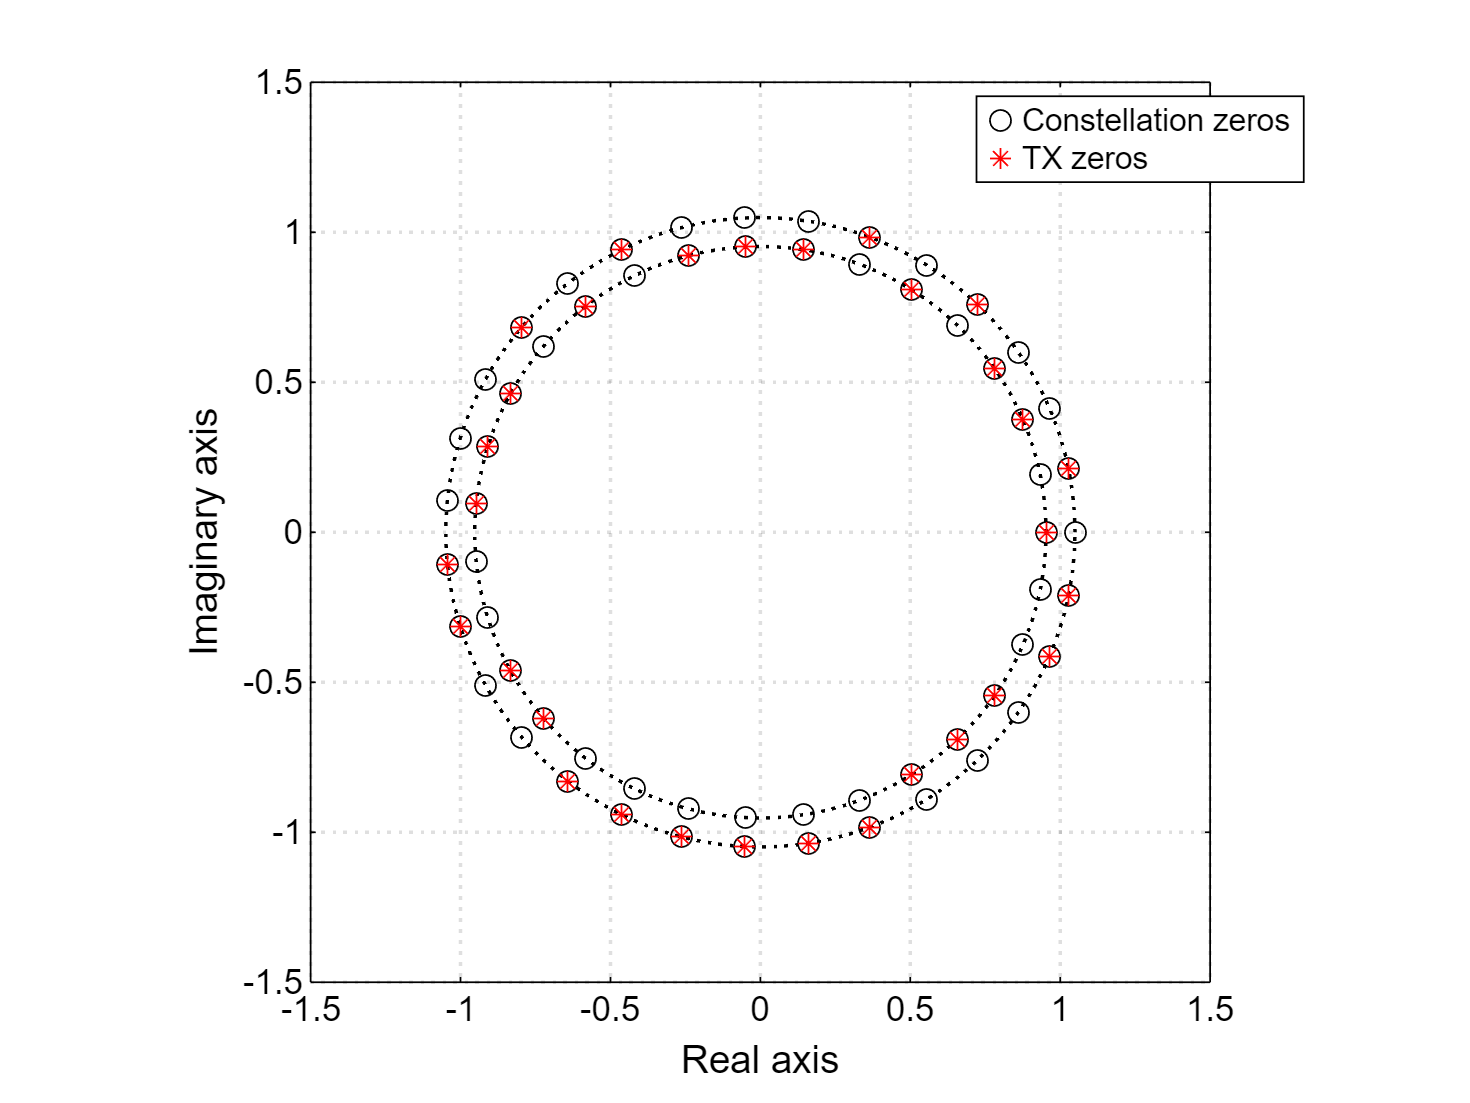

% Map message to zero pattern and J-BMOCZ polynomial
[polyTX, zerosTX] = jbmoczMessageToPoly(codewordTX, R, 1, K+1);

% Generate all zeros in the constellation (for plotting)
constellationZeros = generateAllZeros(K, R, 1);

% Plot the TX zeros
theta = linspace(0, 2*pi, 100);
Router = R * exp(1j*theta); Rinner = 1/R * exp(1j*theta);

f1 = figure(1);
grid on; box on; hold on; axis square;
ax = gca; ax.GridLineStyle = ':'; ax.GridLineWidth = 1;

lgd = legend; lgd.AutoUpdate = 'off';

plot(real(Rinner), imag(Rinner), 'k:')
plot(real(Router), imag(Router), 'k:')

lgd.AutoUpdate = 'on';

scatter(real(constellationZeros(:)), imag(constellationZeros(:)), 'ko', 'DisplayName', 'Constellation zeros')
scatter(real(zerosTX), imag(zerosTX), 'r*', 'DisplayName', 'TX zeros')

xlabel('Real axis')
ylabel('Imaginary axis')

lgd.Location = 'best';

Perturb the TX polynomial with AWGN (at an $E_\mathrm{b}/N_0$ of your choosing), and rotate its zeros through an angle $\phi\sim\mathcal{U}[0,2\pi]$. 

Plot the RX zeros.

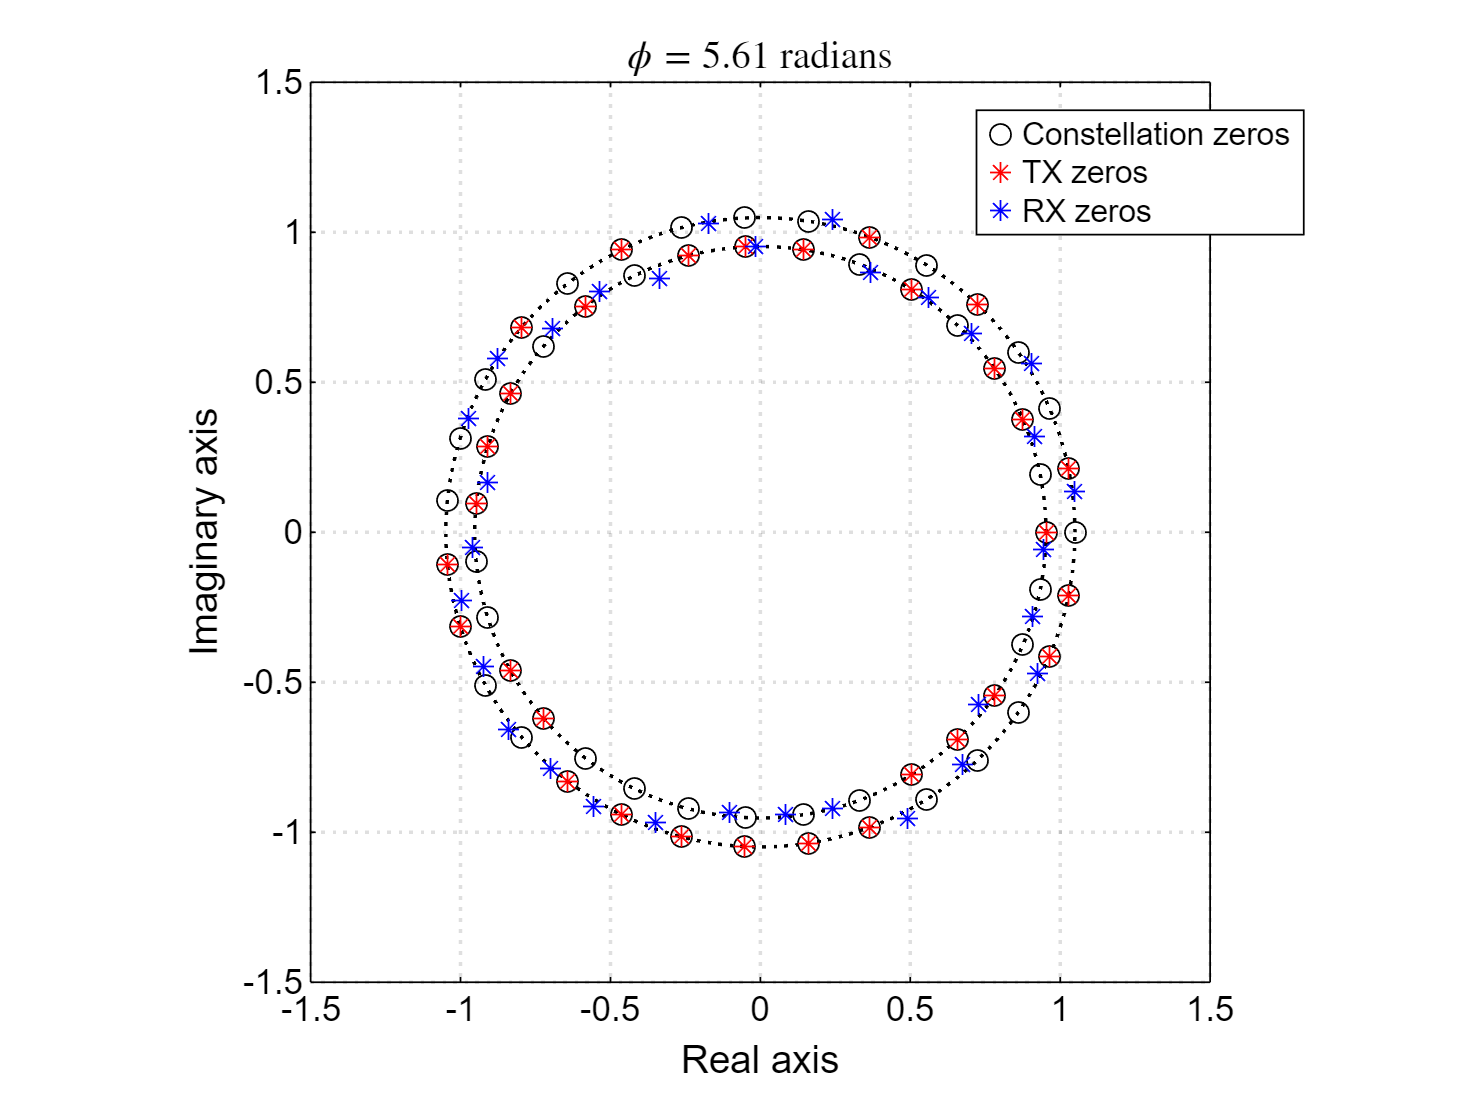

EbN0 = 12;  % dB

% Get N0 on a linear scale (here we assume Es = 1, i.e., the coefficient energy is K+1)
EsN0 = EbN0 + 10*log10(B/(K+1));
N0 = 10 ^ (-EsN0/10);

% Generate AWGN
w = sqrt(N0/2) * (randn(size(polyTX)) + 1j*randn(size(polyTX)));

% Get random phase angle (for zero rotation)
posAngles = linspace(0, 2*pi, 1000);
phi = posAngles(randi([1, 1000], 1, 1));

% Compute RX polynomial (and its roots)
polyRX = (polyTX + w) .* exp(1j*phi*(0:K)).';
zerosRX = roots(polyRX);

% Plot the RX zeros
s = scatter(real(zerosRX), imag(zerosRX), 'b*', 'DisplayName', 'RX zeros');
title(sprintf('$\\phi = %.2f$ radians', phi), 'Interpreter', 'latex')

Set the oversampling factor $\texttt{Q}\geq2$ for the IDFT-based DiZeT decoder and decode the RX polynomial with $\texttt{idftDizet()}$.  

Correct the fractional component of the zero rotation (this step is for illustrative purposes and is not necessary in practice).

Plot the RX zeros following correction.

**Note:** the variable $\texttt{Q}$ controls the resolution of $\epsilon$, i.e., the resolution of the fractional zero rotation estimate. Specifically, the interval $[0,1)$ is quantized into $\texttt{Q}$ uniform bins.

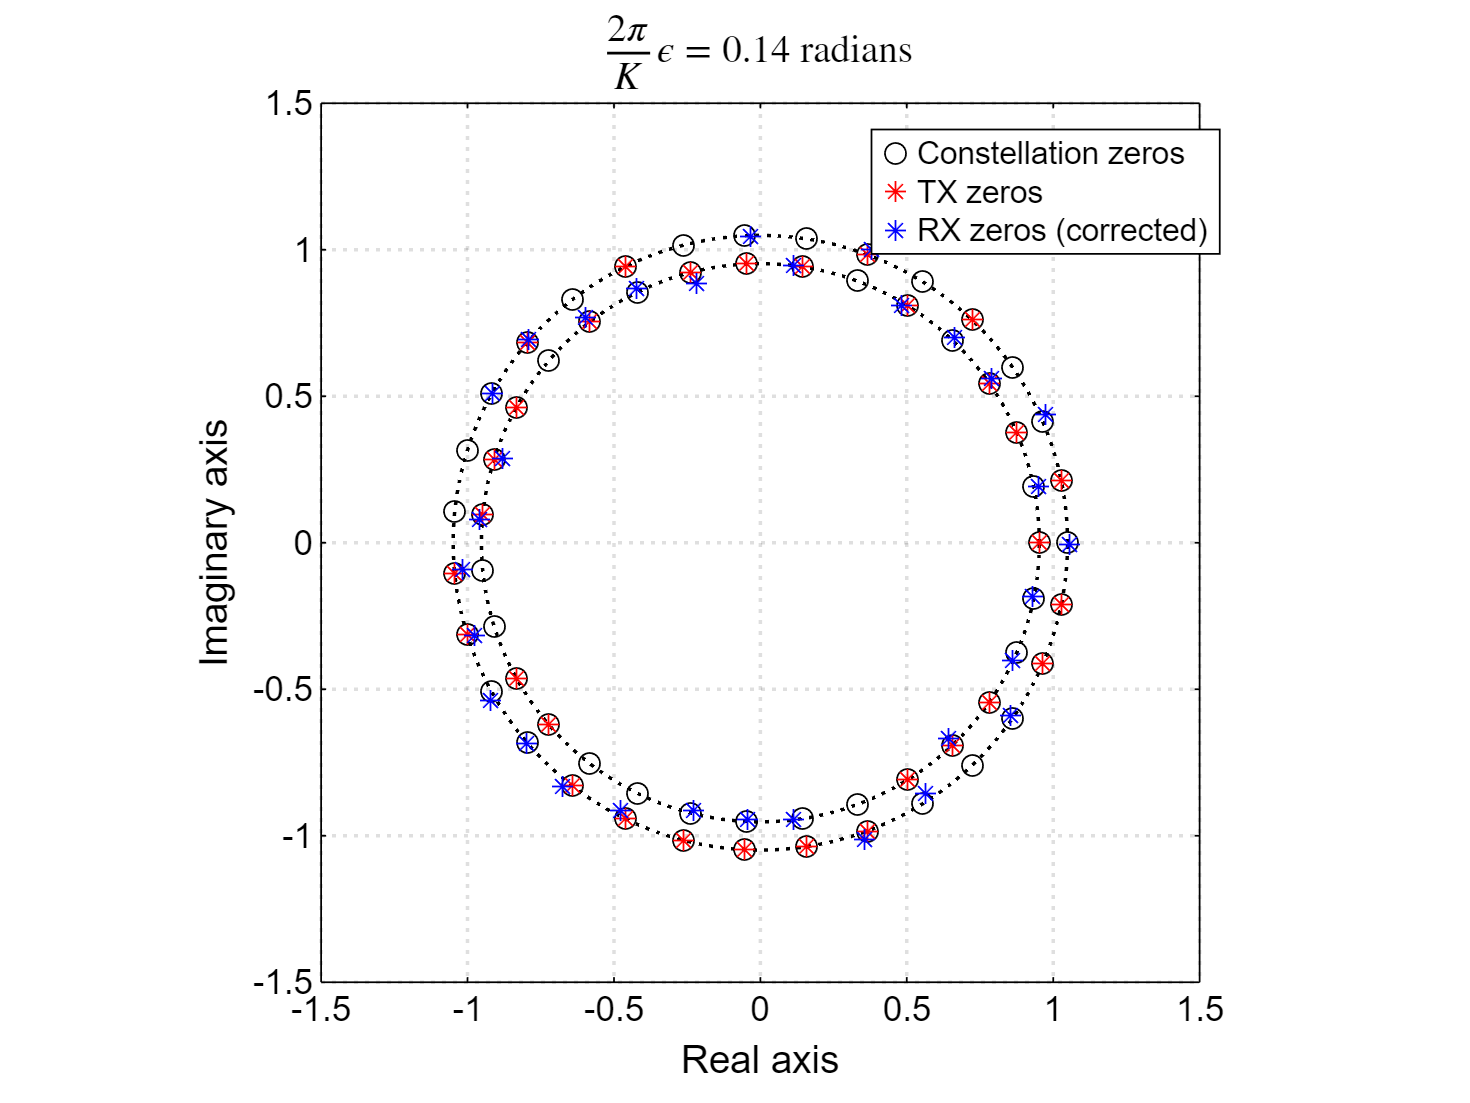

Q = 256;  % Oversampling factor

% Oversampled DiZeT decoding
[codewordRX, epHat] = idftDizet(polyRX, Q, R);

% Correct the fractional zero rotation
phiHatFrac = 2*pi/K*epHat;
polyRXcorrected = polyRX .* exp(-1j*phiHatFrac*(0:K)).';
zerosRXcorrected = roots(polyRXcorrected);

% Plot the corrected zeros
delete(s);
s = scatter(real(zerosRXcorrected), imag(zerosRXcorrected), 'b*', 'DisplayName', 'RX zeros (corrected)');
title(sprintf('$\\frac{2\\pi}{K}\\epsilon = %.2f$ radians', phiHatFrac), 'Interpreter', 'latex')

Decode the RX codeword using $\texttt{acpcDecode()}$and return the estimated integer component of the zero rotation. 

Print the number of bit errors.

% Decode the RX codeword
[messageRX, integerShift] = acpcDecode(codewordRX, Htilde, goutn, HoutTilde, cosetLeaders);

% Print the number of bit errors
numBitErrors = sum(abs(messageRX - messageTX), 'all')

numBitErrors = 0